G = 0.03*((10*s+1)/(s))*(1/((0.5*s+1)))*(1/(0.05*s+1))*1

$$G = \frac{3\,\left(10\,s+1\right)}{100\,s\,\left(\frac{s}{2}+1\right)\,\left(\frac{s}{20}+1\right)}$$

% Compute simplified symbolic expression
simplifiedExpr = expand(G)

$$simplifiedExpr = \frac{3\,s}{10\,\left(\frac{s^{3}}{40}+\frac{11\,s^{2}}{20}+s\right)}+\frac{3}{100\,\left(\frac{s^{3}}{40}+\frac{11\,s^{2}}{20}+s\right)}$$

% bode for normalized G
H = tf([0.3 0.03],[1/40 11/20 1 0])

H =
 
        0.3 s + 0.03
  ------------------------
  0.025 s^3 + 0.55 s^2 + s
 
Continuous-time transfer function.



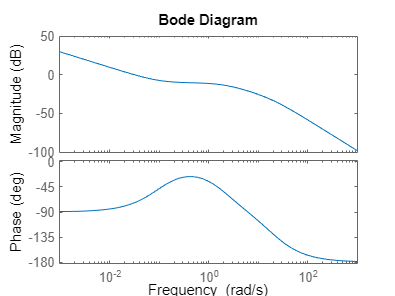

bode(H)

[mag,phase,wout] = bode(H);
mag = squeeze(mag);
phase = squeeze(phase);
wq = interp1(phase, wout, -150)

wq = 38.9280

[a,b,c ]=bode(H,wq);
a

a = 0.0070

wq = interp1(phase, wout, -180)

wq = NaN

%[a,b,c ]=bode(H,wq);